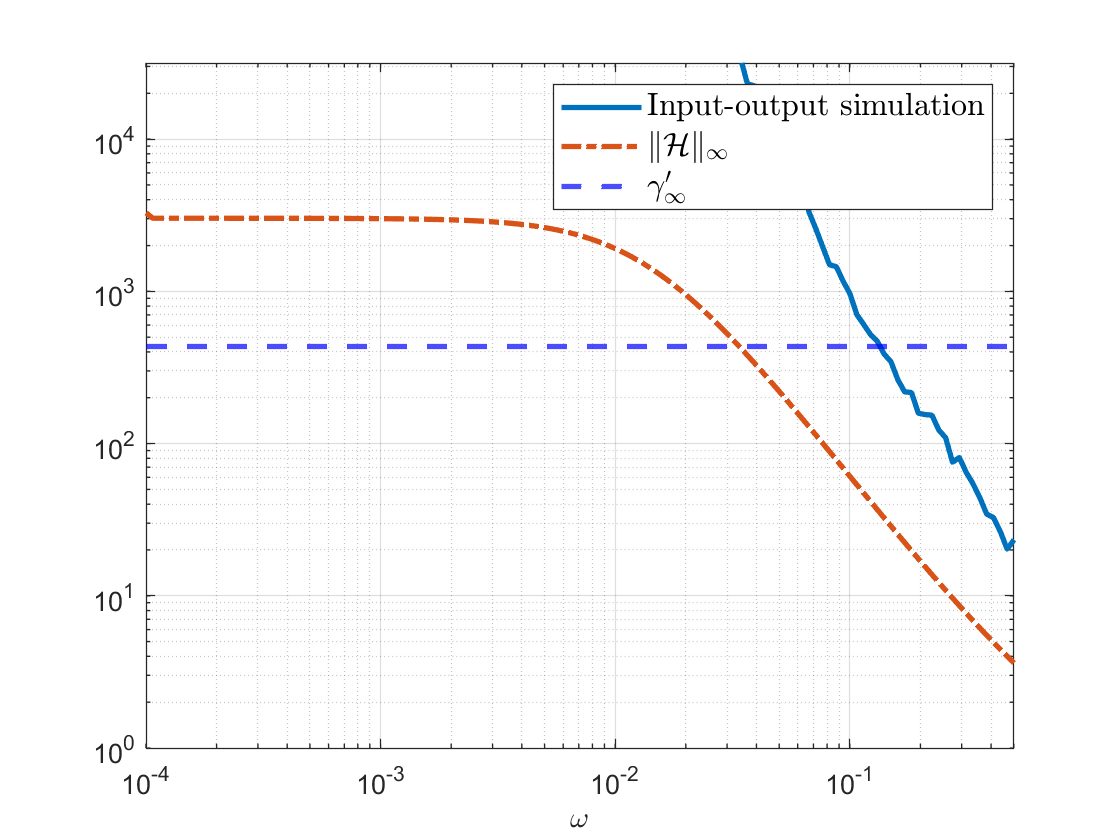

nnn = logspace(-4, -0.3, 128);

figure
plot(nnn,local_results{1, 1}.G_norm,'LineWidth', 2);
hold on; 
plot(nnn, local_results{1, 1}.gain,'-.','LineWidth', 2 );
yline(sqrt(mu_LMI), '--b', 'LineWidth', 2);
set(gca, 'XScale', 'log','YScale', 'log');    % log scale
xlabel('$\omega$','Interpreter','latex');
xlim([10^(-4) 10^(-0.3)]);
ylim([1 10^(4.5)]);
% ylabel('gain');
legend('Input-output simulation','$\|\mathcal{H}\|_\infty$','$\gamma^\prime_\infty$','Interpreter','latex', 'FontSize', 12);
grid on;
saveas(gcf, 'Gnorm_SVD_plot.png');